# Daily Report Generation of JP Pilot Systems

### Importing Data


[filename,path]=uigetfile(".csv");
T=readtable(strcat(path,filename));
time=T.EventTime;
warning('off','MATLAB:table:ModifiedAndSavedVarnames')
fprintf("Data imported.")

Data imported.

### Verifying if the Bus voltages stary out of bounds

%verify DC bus voltages are within range
vinv1=T.Vinv1_rms;
vbus_max=450;
vbus_min=350;
vbus=T.Vbus;
%verify overall bus voltages
if(any(vbus>vbus_max & vbus<vbus_min))
    fprintf("DC bus voltage is not within 350V and 450V \n");
end
    %verify individual capacitor voltages
vbusc1=T.Vbus_c1;
if(any(vbusc1>vbus_max/2 & vbusc1<vbus_min/2))
    fprintf("DC bus C1 voltage is not within 350V and 450V\n");
end
vbusc2=T.Vbus_c2;
if(any(vbusc2>vbus_max/2 & vbusc2<vbus_min/2))
    fprintf("DC bus C2 voltage is not within 350V and 450V\n");
end
clear vbus vbusc1 vbusc2 vbus_max vbus_min
fprintf("vbus data validated")

vbus data validated

### Checking whether a grid outage has occured

- grid outage check by loss of grid frequency

- in an event of grid loss, check if inverter tripped because of it

- No message in this section mean no trip, no grid loss

There was a Power Outage at : 13/01/2025 13:45


Inverter Trip occured

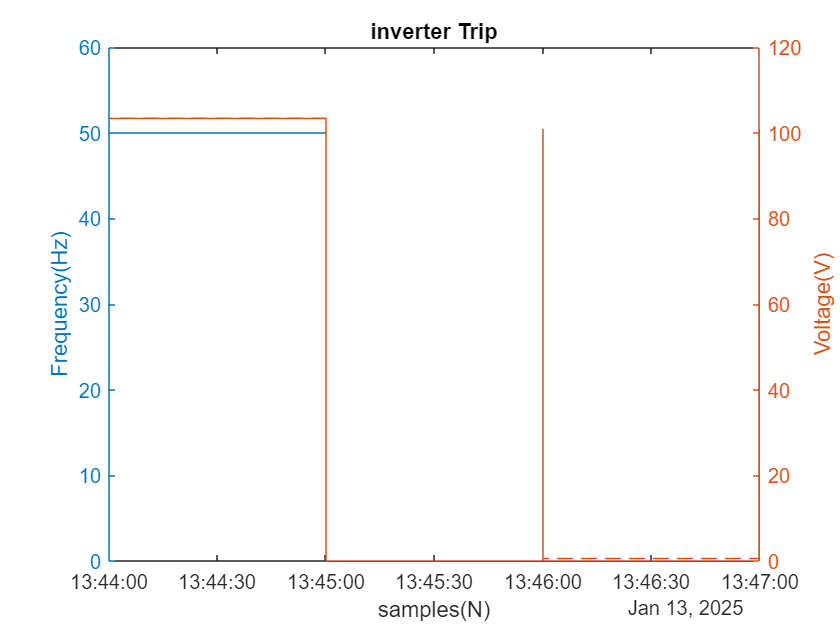

%Loss of grid event
Fgrid=T.Fgrid;
Fgrid_min=45;
%assert(all(T.Fgrid<45),'There was a power outage');
if any(Fgrid < Fgrid_min)
   [loc]=find(Fgrid<Fgrid_min);
   time_stamp=T.EventTime(loc(1));
   fprintf("There was a Power Outage at : %s\n",time_stamp)
   %check for inverter trip
   if(T.Vinv1_rms(loc(1)+10)<150)
       fprintf("Inverter Trip occured")
       figure
       title("inverter Trip")
       tmin=loc(1)-100;
       tmax=loc(1)+100;
       yyaxis left
       plot(time(tmin:tmax),Fgrid(tmin:tmax))
       ylabel("Frequency(Hz)")
       yyaxis right
       plot(time(tmin:tmax),T.Vinv1_rms(tmin:tmax))
       hold on
       plot(time(tmin:tmax),T.Vinv2_rms(tmin:tmax))
       hold off
       ylabel("Voltage(V)")
       xlabel("samples(N)")

   end
end

fprintf("Grid outage validated\n");

Grid outage validated


### PV Energy Production(kWh)

Epv=T.Epv;
if(Epv(end)<Epv(1)+10)
    fprintf("No PV Energy Generation\n");
else
    fprintf("Pv Energy Generated = %0.2f kWh\n",(Epv(end)-Epv(1))/1000);
end

Pv Energy Generated = 0.06 kWh


### Temperature Validation

% 
% Tinv=T.Inv_t;
% figure
% plot(time,T.Batt_t)
% hold on
% plot(time,T.Inv_t)
% hold on
% plot(time,T.Pv_t)
% hold on
% plot(time,T.Amb_t)
% hold on
% plot(time,T.Cm4_t)
% hold off
% title("Temperature Validation")
% legend("Battery-temp","Inverter-temp","PV-temp","Ambient-temp","CM4-temp",'location','best')
% ylabel("Temperature (°C)");
% xlabel("Event time")
% grid on


Temperature Stats

% Assuming T is a structure containing the temperature data
Tinv_average = mean(T.Inv_t);
Tbat_average = mean(T.Batt_t);
Tpv_average = mean(T.Pv_t);
Tamb_average = mean(T.Amb_t);
TCM4_average = mean(T.Cm4_t);

Tinv_min = min(T.Inv_t);
Tbat_min = min(T.Batt_t);
Tpv_min = min(T.Pv_t);
Tamb_min = min(T.Amb_t);
TCM4_min = min(T.Cm4_t);

Tinv_max = max(T.Inv_t);
Tbat_max = max(T.Batt_t);
Tpv_max = max(T.Pv_t);
Tamb_max = max(T.Amb_t);
TCM4_max = max(T.Cm4_t);

% Create a table to display the results
temperature_data = table([Tinv_average; Tbat_average; Tpv_average; Tamb_average; TCM4_average], ...
                         [Tinv_min; Tbat_min; Tpv_min; Tamb_min; TCM4_min], ...
                         [Tinv_max; Tbat_max; Tpv_max; Tamb_max; TCM4_max], ...
    'VariableNames', {'Average (°C)', 'Min (°C)', 'Max (°C)'}, ...
    'RowNames', {'Inverter-temp', 'Battery-temp', 'PV-temp', 'Ambient-temp', 'CM4-temp'});

% Display the table
disp(temperature_data);

                     Average (°C)    Min (°C)    Max (°C)
                     ____________    ________    ________

    Inverter-temp       10.782          8.9        12.3  
    Battery-temp        9.8239          8.9        10.9  
    PV-temp              11.55            9        15.1  
    Ambient-temp         20.65         20.5        20.9  
    CM4-temp            42.123         40.8        43.8  





%Temp Design limits violations
%comment here after visualizing the plots and tables



### Evaluating Trips

#### Checking for Trip_1

% Initialize previous fault code to an invalid value (e.g., 0)
previous_fault_code = 0;

if(any(T.Trips_1 > 0))
    [Trip_1] = find(T.Trips_1 > 0);
    
    % Iterate over the trips to handle repeated faults
    for i = 1:length(Trip_1)
        current_fault_code = T.Trips_1(Trip_1(i));
        
        % Only display the fault if it's different from the previous one
        if current_fault_code ~= previous_fault_code
            fprintf("There was a Trip at %s \n", time(Trip_1(i)));
            
            % Call the function to decode faults
            faults = decode_trip1(current_fault_code);
            
            % Display the results
            for j = 1:length(faults)
                fprintf('Fault-Code = %s\nFaultName = %s\nDescription = %s\n', faults(j).FaultCode, faults(j).FaultName, faults(j).FaultDescription);
                fprintf("...\n\n");
            end
            
        else
            % Skip if it's the same fault as the previous one
            %fprintf("Same fault as previous, skipping.\n");
        end
        
        % Update the previous fault code
        previous_fault_code = current_fault_code;
    end
else
    fprintf("There was no Trip here.\n");
end

There was a Trip at 13/01/2025 13:43 


Fault-Code = FLT 083832.SEInverter
FaultName = Iinv1_OC_Trip
Description = Over current on inverter phase 1.


...



There was a Trip at 13/01/2025 13:43 


Fault-Code = FLT 083832.SEInverter
FaultName = Iinv1_OC_Trip
Description = Over current on inverter phase 1.


...



Fault-Code = FLT 083833.SEInverter
FaultName = Iinv2_OC_Trip
Description = Over current on inverter phase 2.


...



There was a Trip at 13/01/2025 13:45 


Fault-Code = FLT 083832.SEInverter
FaultName = Iinv1_OC_Trip
Description = Over current on inverter phase 1.


...



#### Checking for Trip_2

fprintf("Checking for Trip2\n");

Checking for Trip2


% Initialize previous fault code to an invalid value (e.g., 0)
previous_fault_code = 0;

% Check if there are any trips (faults)
if any(T.Trips_2 > 0)
    % Find the indices where faults occur
    [Trip_2] = find(T.Trips_2 > 0);
    
    % Loop through the trips and analyze faults
    for i = 1:length(Trip_2)
        current_fault_code = T.Trips_2(Trip_2(i));

        % Only display the fault if it's different from the previous one
        if current_fault_code ~= previous_fault_code
            % Display the timestamp when the fault occurs
            fprintf("There was a Trip at %s \n", time(Trip_2(i)));
            
            % Call the function to decode the fault code
            faults = decode_trip2(current_fault_code);
            
            % Display the decoded fault details
            for j = 1:length(faults)
                fprintf('Fault-Code = %s\nFaultName = %s\nDescription = %s\n', faults(j).FaultCode, faults(j).FaultName, faults(j).FaultDescription);
                fprintf("...\n");
            end
        else
            % Skip if it's the same fault as the previous one
           % fprintf("Same fault as previous, skipping.\n");
        end

        % Update the previous fault code
        previous_fault_code = current_fault_code;
    end
else
    fprintf("There was no Trip here.\n");
end

There was a Trip at 13/01/2025 13:43 


Fault-Code = FLT 08848.SEInverter
FaultName = DC_Component_Trip
Description = DC component of the grid current is greater than 1% of rated current.


...


There was a Trip at 13/01/2025 13:43 


Fault-Code = FLT 08849.SEInverter
FaultName = Phase1_overload_Trip
Description = Overload occurred on inverter phase 1.


...


### Evaluating Alerts

#### Checking Alerts_1


% Initialize previous alert code to an invalid value (e.g., 0)
previous_alert_code = 0;

% Check if there are any alerts (warnings)
if any(T.Alerts_1 > 0)
    % Find the indices where alerts occur
    [Alert_1] = find(T.Alerts_1 > 0);
    
    % Loop through the alerts and analyze them
    for i = 1:length(Alert_1)
        current_alert_code = T.Alerts_1(Alert_1(i));

        % Only display the alert if it's different from the previous one
        if current_alert_code ~= previous_alert_code
            % Display the timestamp when the alert occurs
            fprintf("There was an Alert at %s \n", time(Alert_1(i)));
            
            % Call the function to decode the alert code
            alerts = decode_alerts1(current_alert_code);
            
            % Display the decoded alert details
            for j = 1:length(alerts)
                fprintf('Alert-Code = %s\nAlertName = %s\nDescription = %s\n', alerts(j).AlertCode, alerts(j).AlertName, alerts(j).AlertDescription);
                fprintf("...\n");
            end
        else
            % Skip if it's the same alert as the previous one
            %fprintf("Same alert as previous, skipping.\n");
        end

        % Update the previous alert code
        previous_alert_code = current_alert_code;
    end
else
    fprintf("There was no Alert here.\n");
end

There was an Alert at 13/01/2025 13:45 


Alert-Code = WAR 08801.SEInverter
AlertName = Grid_UV_Disconnection
Description = Grid Undervoltage warning


...


Alert-Code = WAR 08803.SEInverter
AlertName = Grid_UF_Disconnection
Description = Grid Under frequency warning


...


Alert-Code = WAR 08806.SEInverter
AlertName = Active_Method_Grid_Disconnect
Description = Disconnected from the grid due to active islanding.


...


There was an Alert at 13/01/2025 13:46 


Alert-Code = WAR 08801.SEInverter
AlertName = Grid_UV_Disconnection
Description = Grid Undervoltage warning


...


Alert-Code = WAR 08803.SEInverter
AlertName = Grid_UF_Disconnection
Description = Grid Under frequency warning


...


There was an Alert at 13/01/2025 13:47 


Alert-Code = WAR 08803.SEInverter
AlertName = Grid_UF_Disconnection
Description = Grid Under frequency warning


...


#### Check for Alerts_2


% Initialize previous alert code to an invalid value (e.g., 0)
previous_alert_code = 0;

% Check if there are any alerts (warnings)
if any(T.Alerts_2 > 0)
    % Find the indices where alerts occur
    [Alert_2] = find(T.Alerts_2 > 0);
    
    % Loop through the alerts and analyze them
    for i = 1:length(Alert_2)
        current_alert_code = T.Alerts_2(Alert_2(i));

        % Only display the alert if it's different from the previous one
        if current_alert_code ~= previous_alert_code
            % Display the timestamp when the alert occurs
            fprintf("There was an Alert at %s \n", time(Alert_2(i)));
            
            % Call the function to decode the alert code
            alerts = decode_alerts_2(current_alert_code);
            
            % Display the decoded alert details
            for j = 1:length(alerts)
                fprintf('Alert-Code = %s\nAlertName = %s\nDescription = %s\n', alerts(j).AlertCode, alerts(j).AlertName, alerts(j).AlertDescription);
                fprintf("...\n");
            end
        else
            % Skip if it's the same alert as the previous one
            %fprintf("Same alert as previous, skipping.\n");
        end

        % Update the previous alert code
        previous_alert_code = current_alert_code;
    end
else
    fprintf("There was no Alert here.\n");
end

There was an Alert at 13/01/2025 13:43 


Alert-Code = WAR 08820.SEInverter
AlertName = PV3_UV_Alert
Description = Gate Block PV3 converter due to UV


...


There was an Alert at 13/01/2025 13:46 


Alert-Code = WAR 08818.SEInverter
AlertName = PV1_UV_Alert
Description = Gate Block PV1 converter due to UV


...


Alert-Code = WAR 08820.SEInverter
AlertName = PV3_UV_Alert
Description = Gate Block PV3 converter due to UV


...


There was an Alert at 13/01/2025 13:46 


Alert-Code = WAR 08818.SEInverter
AlertName = PV1_UV_Alert
Description = Gate Block PV1 converter due to UV


...


Alert-Code = WAR 08819.SEInverter
AlertName = PV2_UV_Alert
Description = Gate Block PV2 converter due to UV


...


Alert-Code = WAR 08820.SEInverter
AlertName = PV3_UV_Alert
Description = Gate Block PV3 converter due to UV


...


There was an Alert at 13/01/2025 13:49 


Alert-Code = WAR 08819.SEInverter
AlertName = PV2_UV_Alert
Description = Gate Block PV2 converter due to UV


...


Alert-Code = WAR 08820.SEInverter
AlertName = PV3_UV_Alert
Description = Gate Block PV3 converter due to UV


...


There was an Alert at 13/01/2025 13:49 


Alert-Code = WAR 08820.SEInverter
AlertName = PV3_UV_Alert
Description = Gate Block PV3 converter due to UV


...
